load(['PD_total_data.mat'])
% 假设data是3×N的数组，包含[x坐标; y坐标; 数值]

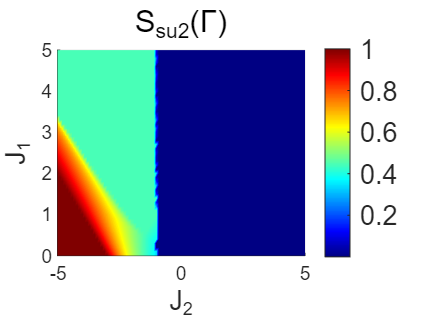

data = SSF123_Gamma_Data; 
J2_unique = -5:0.1:5;
J1_unique = 0:0.1:5;
[J_2,J_1]=meshgrid(J2_unique,J1_unique);
S=zeros(size(J_2,1),size(J_1,2));
for i=1:size(J_2,1)
    for j=1:size(J_1,2)
        Index_X=find(abs(data(1,:)-J_2(i,j))<1e-4);
        Index_Y=find(abs(data(2,:)-J_1(i,j))<1e-4);
        index=intersect(Index_X,Index_Y);
        if(numel(index)>1)
            error(sprintf("%d,%d,multiple index",i,j));
        end
        if(numel(index)==0)
            error(sprintf("%d,%d,empty index",i,j));
        end
        S(i,j)=data(3,index)/9;
    end
end


% 绘制曲面图
figure;
surf(J_2,J_1,S);
xlabel('J_2','FontSize',13);
ylabel('J_1','FontSize',13);
zlabel('Z');
title('S_{su2}(\Gamma)','FontSize',15);
colormap(jet);    % 设置颜色映射
shading interp;    % 平滑着色
colorbar('FontSize',13);          % 显示颜色条

% 可选：调整视角
view(0, 90);     % 设置视角角度

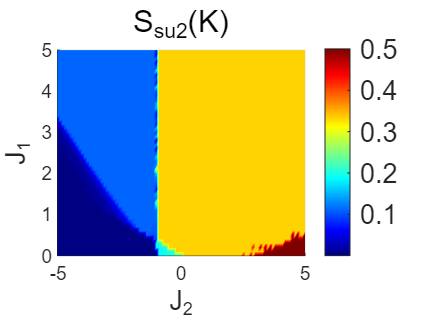

data = SSF123_K_Data; 
J2_unique = -5:0.1:5;
J1_unique = 0:0.1:5;
[J_2,J_1]=meshgrid(J2_unique,J1_unique);
S=zeros(size(J_2,1),size(J_1,2));
for i=1:size(J_2,1)
    for j=1:size(J_1,2)
        Index_X=find(abs(data(1,:)-J_2(i,j))<1e-4);
        Index_Y=find(abs(data(2,:)-J_1(i,j))<1e-4);
        index=intersect(Index_X,Index_Y);
        if(numel(index)>1)
            error(sprintf("%d,%d,multiple index",i,j));
        end
        S(i,j)=data(3,index)/9;
    end
end


% 绘制曲面图
figure;
surf(J_2,J_1,S);
xlabel('J_2','FontSize',13);
ylabel('J_1','FontSize',13);
zlabel('Z');
title('S_{su2}(K)','FontSize',15);
colormap(jet);    % 设置颜色映射
shading interp;    % 平滑着色
colorbar('FontSize',13);          % 显示颜色条

% 可选：调整视角
view(0, 90);     % 设置视角角度

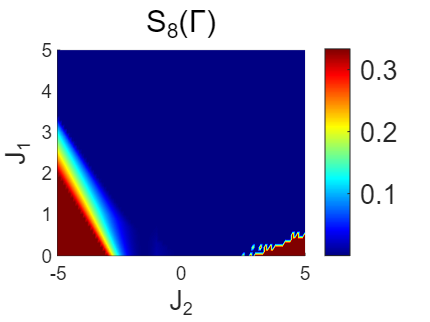

data = SSF8_Gamma_Data; 
J2_unique = -5:0.1:5;
J1_unique = 0:0.1:5;
[J_2,J_1]=meshgrid(J2_unique,J1_unique);
S=zeros(size(J_2,1),size(J_1,2));
for i=1:size(J_2,1)
    for j=1:size(J_1,2)
        Index_X=find(abs(data(1,:)-J_2(i,j))<1e-4);
        Index_Y=find(abs(data(2,:)-J_1(i,j))<1e-4);
        index=intersect(Index_X,Index_Y);
        if(numel(index)>1)
            error(sprintf("%d,%d,multiple index",i,j));
        end
        if(numel(index)==0)
            error(sprintf("%d,%d,Empty index",i,j));
        end
        S(i,j)=data(3,index)/9;
    end
end


% 绘制曲面图
figure;
surf(J_2,J_1,S);
xlabel('J_2','FontSize',13);
ylabel('J_1','FontSize',13);
zlabel('Z');
title('S_{8}(\Gamma)','FontSize',15);
colormap(jet);    % 设置颜色映射
shading interp;    % 平滑着色
colorbar('FontSize',13);          % 显示颜色条

% 可选：调整视角
view(0, 90);     % 设置视角角度

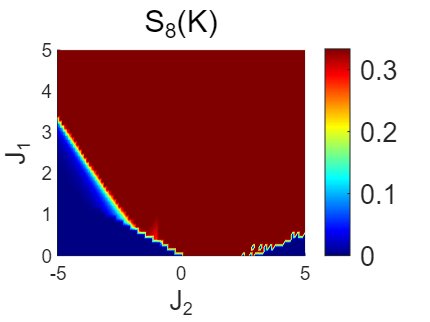

data = SSF8_K_Data; 
J2_unique = -5:0.1:5;
J1_unique = 0:0.1:5;
[J_2,J_1]=meshgrid(J2_unique,J1_unique);
S=zeros(size(J_2,1),size(J_1,2));
for i=1:size(J_2,1)
    for j=1:size(J_2,2)
        Index_X=find(abs(data(1,:)-J_2(i,j))<1e-4);
        Index_Y=find(abs(data(2,:)-J_1(i,j))<1e-4);
        index=intersect(Index_X,Index_Y);
        if(numel(index)>1)
            error(sprintf("%d,%d,multiple index",i,j));
        end
        S(i,j)=data(3,index)/9;
    end
end


% 绘制曲面图
figure;
surf(J_2,J_1,S);
xlabel('J_2','FontSize',13);
ylabel('J_1','FontSize',13);
zlabel('Z');
title('S_{8}(K)','FontSize',15);
colormap(jet);    % 设置颜色映射
shading interp;    % 平滑着色
colorbar('FontSize',13);          % 显示颜色条

% 可选：调整视角
view(0, 90);     % 设置视角角度